# Lasso Plot with Default Plot Type

Load the sample data

load acetylene

Prepare the design matrix for lasso fit with interactions.

X = [x1 x2 x3];
D = x2fx(X,'interaction');
D(:,1) = []; % No constant term

The [`x2fx`](docid:stats_ug.f1133165) function returns the quadratic model in the order of a constant term, linear terms and interaction terms: constant term, `x1`, `x2`, `x3`, `x1.*x2`, `x1.*x3`, and `x2.*x3`

Fit a regularized model of the data using `lasso`.

B = lasso(D,y);

Plot the lasso fits with labeled coefficients by using the `PredictorNames` name-value pair.

lassoPlot(B,'PredictorNames',{'x1','x2','x3','x1.*x2','x1.*x3','x2.*x3'});
legend('show','Location','NorthWest') % Show legend

Each line represents a trace of the values in B for a single predictor variable: `x1`, `x2`, `x3`, `x1.*x2`, `x1.*x3`, and `x2.*x3`.

Display a data tip for the trace plot. A data tip appears when you hover over a data tip.

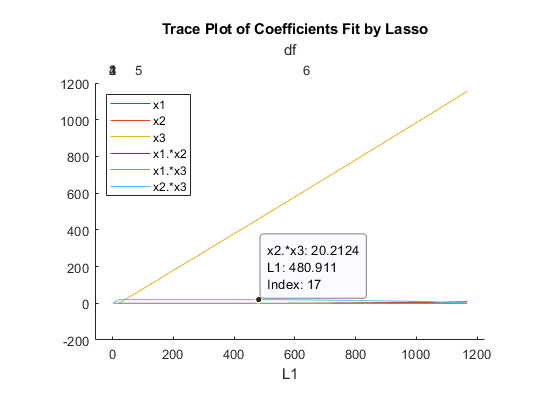

A data tip displays these lines of information: the name of the selected coefficient with a fitted value, the L1 norm of a set of coefficients including the selected coefficient, and the index of the corresponding Lambda.